# Pràctica 7. Exercici 3

Exercici 7 del document CN_full4.pdf

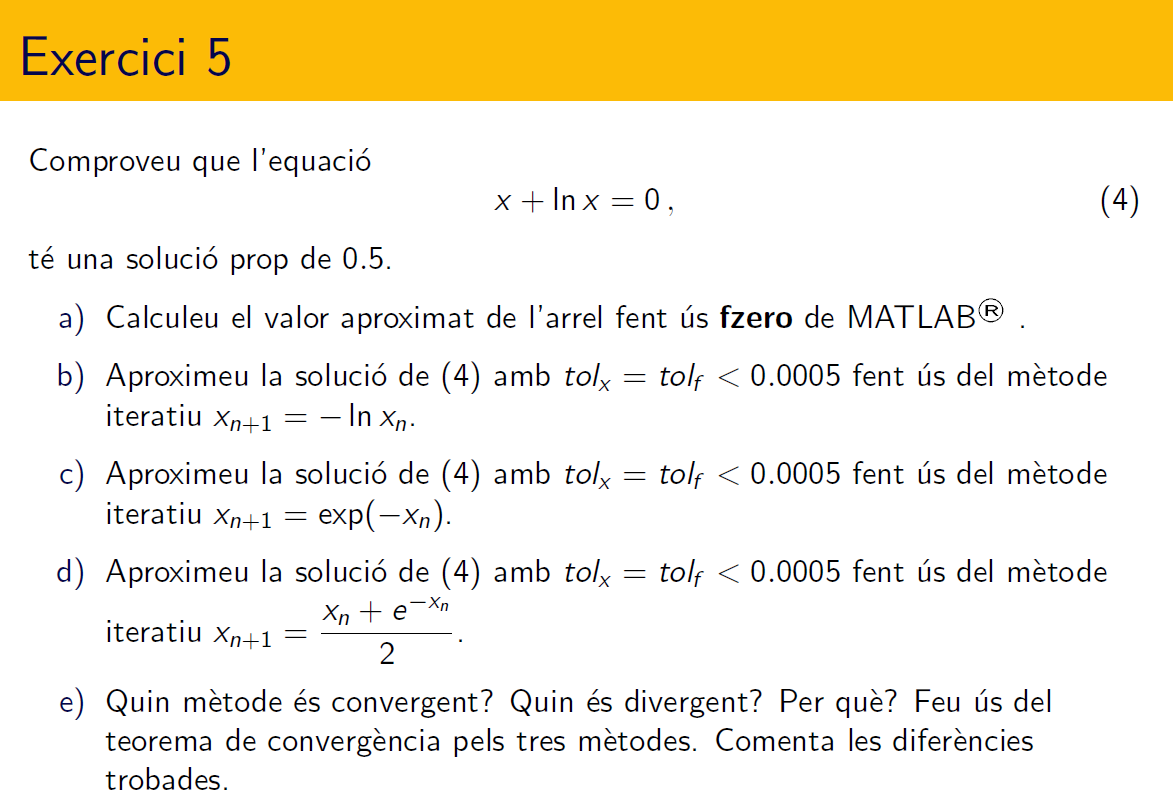

================================================================================

- `Comproveu que l'equació té una solució prop de 0.5`

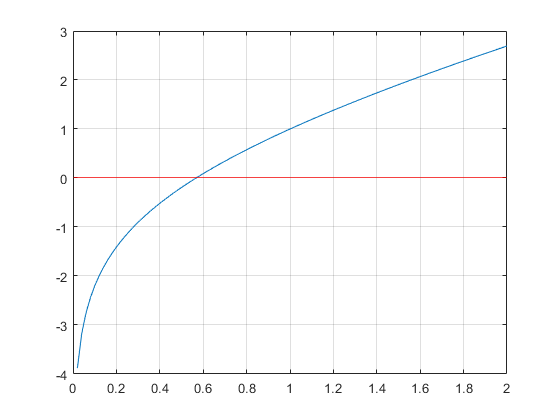

t = linspace(0,2);
f = @(x) x+log(x);
plot(t,f(t)), yline(0,'r'), grid

alpha = fzero(f,[0.4,0.8])

alpha =       0.56714


- `Determineu la solució aproximada fent ús del mètode `$x_{n+1} = -\ln x_n$,` preneu `$tol_x = tol_f <0.0005$.

g1 = @(t) -log(t);
[x,~,n] = func_iter(g1,2,0.0005,20)

x =      -0.72282 -     1.9293i


n =     19


- `Determineu la solució aproximada fent ús del mètode `$x_{n+1} = \exp (-x_n)$,` preneu `$tol_x = tol_f <0.0005$.

g2 = @(t) exp(-t);
[x,~,n] = func_iter(g2,2,0.0005,20)

x =       0.56745


n =     13


- `Determineu la solució aproximada fent ús del mètode `$$x_{n+1}= \displaystyle\frac{x_n+e^{-x_n}}{2}$,` preneu `$tol_x = tol_f <0.0005$.

g3 = @(t) (t+exp(-t))/2;
[x,~,n] = func_iter(g3,2,0.0005,20)

x =       0.56748


n =      5


- `Quin mètode és convergent? Quin és divergent? Per què? Feu ús del teorema de convergència pels tres mètodes. Comenta les diferències trobades.`

syms t
dg1(t) = diff(g1,t), dg2(t) = diff(g2,t), dg3(t) = diff(g3,t)

$$dg1(t) = -\frac{1}{t}$$

$$dg2(t) = -{\mathrm{e}}^{-t}$$

$$dg3(t) = \frac{1}{2}-\frac{{\mathrm{e}}^{-t}}{2}$$

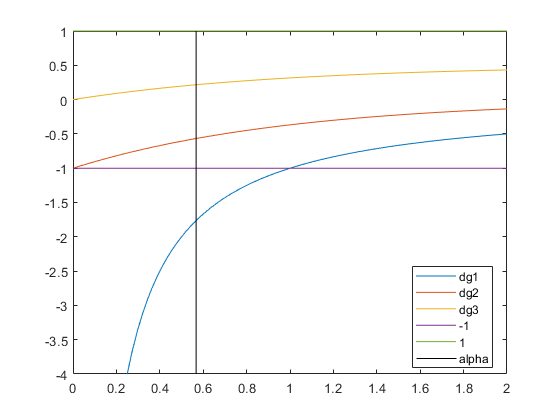

fplot([dg1,dg2,dg3,-1,1],[0,2]), ylim([-4,1])
hold on
line([alpha,alpha],[-4,1],'Color','k'),hold off
legend('dg1','dg2','dg3','-1','1','alpha','Location','best')

% g2,g3 convergent, g1 divergent
